# Bluetooth Mesh Library Tests

This is a modified version of the BLEMeshNetworkFloodingExample.mlx file. Most of the stuff here is tests, to get a feel for how to correctly model the proposed provisioning algorithm. Seems like there's no way to simulate the provisioning process specifficaly as this model is meant for an already provisioned network. This limitation could be overcome by running **multiple simulations with a growing number of provisioned nodes.**

## Bluetooth Mesh Network Flooding Scenarios

This example uses the advertising bearer to demonstrate managed flooding. This example enables you to create and configure two Bluetooth mesh network scenarios. Each scenario is a multinode mesh network. Each scenario classifies the mesh nodes as node, relay node, source node, and destination node.

- Node: Any device in the mesh network

- Relay node: A node that has the relay feature supported and enabled

- Source node: A node that originates and transmits packets

- Destination node: A node at which the packets from the source node are destined

The first mesh network scenario consists of 21 mesh nodes, including relay nodes, a source node, and a destination node. In the second scenario, the example:

- Disables the relay feature of some nodes

- Removes a node from the mesh network

For both the scenarios, you can visualize the message flow in the network and retrieve these statistics.

- Network PDR: Ratio of number of packets received at all the destination nodes to the number of packets transmitted by all the source nodes in the mesh network

- Application end-to-end packet latency in seconds

- Link layer (LL) throughput in Kbps

- Time spent in listen state, transmit state, idle state and sleep state in seconds

- Packet statistics at the application layer, network layer, transport layer, link layer and physical layer

## Check for Support Package Installation

Check if the Communications Toolbox™ Wireless Network Simulation Library support package is installed. If the support package is not installed, MATLAB® returns an error with a link to download and install the support package.

wirelessnetworkSupportPackageCheck;

## Configure Simulation Parameters

Set the seed for the random number generator to 1. The seed value controls the pattern of random number generation. For high fidelity simulation results, change the seed value for each run and average the results over multiple simulations.

rng(1,"twister");

Specify the simulation time for both scenarios.

simulationTime = 0.3; % In seconds

To highlight message transmission in the mesh network visualization, set this flag to `True`.

highlightTransmissions = true;

Number of nodes in the mesh network. We'll start out with two nodes

numNodes = 85;

Get the node positions from the MAT file. Specify the positions of Bluetooth mesh nodes as a `numNodes`-by-2 array, where `numNodes` is the number of nodes in the network. Each row specifies the Cartesian coordinates of a node, starting from the first node.

load("layout_v2_bin.mat");
if numNodes ~= size(bleMeshNetworkNodePositions,1)
    error("Invalid Bluetooth mesh node position value. Specify 'bleMeshNetworkNodePositions' value in the MAT file as a "...
        +num2str(numNodes)+"-by-2 array.");
end

## Simulate Mesh Network Scenario One

The first mesh network scenario consists of 21 mesh nodes. Set some of the nodes as relay nodes and source-destination node pairs. To specify multiple source-destination pairs, update `sourceDestinationPairs` by adding a new row specifying the source and destination nodes.

relayNodes = [1:1:85];
%sourceDestinationPairs = first_test;
sourceDestinationPairs = [13 2; 11 2; 10 2; 9 2; 8 2];
%sourceDestinationPairs = [24 2];

Create a wireless network simulator object.

networkSimulator = wirelessNetworkSimulator.init;

### Create and Configure Bluetooth Mesh Nodes

Initialize array to store Bluetooth mesh nodes. Note: This is some super weird MATLAB syntax it means to create an array of type BluetoothLENode. And it looks like we define it the array to be 0xnumNodes size and the having the 0 dimention there means that the array is empty. If you fill it out it goes from 0 to 1xnumNodes.

nodesScenarioOne = bluetoothLENode.empty(0,numNodes);

Create Bluetooth mesh network for scenario one. Use [`bluetoothMeshProfileConfig`](docid:bluetooth_ref#mw_4cc629a6-0f65-4b67-b33d-d9dcd02e2031) to create mesh profile configuration object. To create a Bluetooth mesh node, use the [`bluetoothLENode`](docid:bluetooth_ref#mw_9e947122-1ba1-401a-8e3c-d4b74ea1461b) object. Specify the role as "`broadcaster-observer"` and assign the mesh profile to `MeshConfig`.

for nodeIndex = 1:numNodes
    % Create and configure Bluetooth mesh profile by specifying the element
    % address (unique to each node in the network). Set network message
    % repetitions to 2, and network transmit interval as a random value in
    % the range [10, 30] milliseconds.
    meshCfg = bluetoothMeshProfileConfig(ElementAddress=dec2hex(nodeIndex,4),...
        NetworkTransmissions=2,NetworkTransmitInterval=randi([1 3])*10e-3);

    % Enable relay feature of the configured relay nodes. Set relay message
    % repetitions to 3, and relay retransmit interval as a random value in
    % the range [10, 30] milliseconds.
    if any(nodeIndex==relayNodes)
        meshCfg.Relay = true;
        meshCfg.RelayRetransmissions = 3;
        meshCfg.RelayRetransmitInterval = randi([1 3])*10e-3;
    end

    % Create and configure Bluetooth mesh node by assigning the mesh profile.
    % Set receiver range, advertising interval (seconds) and scan interval (seconds).
    nodesScenarioOne(nodeIndex) = bluetoothLENode("broadcaster-observer",MeshConfig=meshCfg,...
        Position=[bleMeshNetworkNodePositions(nodeIndex,:) 0],Name="Node"+num2str(nodeIndex),...
        ReceiverRange=6,AdvertisingInterval=20e-3,ScanInterval=25e-3);
end

### Add Application Traffic to Source Nodes

Create a [networkTrafficOnOff](docid:comm_ref#mw_0b2cd92a-350a-4264-9283-db5da34bd041) object to generate an On-Off application traffic pattern. Configure the On-Off application traffic pattern by specifying the application data rate, packet size, on, and off state duration. Use [addTrafficSource](docid:bluetooth_ref#mw_a64be9f6-0400-453b-a913-0f248bb03dfc) object function to attach the application traffic source between the specified source-destination node pairs.

for srcIdx = 1:numel(sourceDestinationPairs)/2
    % Set data rate, packet size, on time, and off time based on the
    % simulation time.
    traffic = networkTrafficOnOff(DataRate=1,PacketSize=15,GeneratePacket=true,...
        OnTime=(simulationTime * 0.3),OffTime=(simulationTime * 0.7));


    % Maximum number of hops for a packet is controlled by setting
    % time-to-live (TTL) value
    ttl = 35;

    % Attach application traffic to source
    addTrafficSource(nodesScenarioOne(sourceDestinationPairs(srcIdx,1)),traffic, ...                        % Traffic object
        SourceAddress=nodesScenarioOne(sourceDestinationPairs(srcIdx,1)).MeshConfig.ElementAddress,...      % Source element address
        DestinationAddress=nodesScenarioOne(sourceDestinationPairs(srcIdx,2)).MeshConfig.ElementAddress,... % Destination element address
        TTL=ttl);

    % Test other direction
    %addTrafficSource(nodesScenarioOne(sourceDestinationPairs(srcIdx,2)),traffic, ...                        % Traffic object
    %    SourceAddress=nodesScenarioOne(sourceDestinationPairs(srcIdx,2)).MeshConfig.ElementAddress,...      % Source element address
    %    DestinationAddress=nodesScenarioOne(sourceDestinationPairs(srcIdx,1)).MeshConfig.ElementAddress,... % Destination element address
    %    TTL=ttl);
    

end

### Visualize Mesh Network

Visualize the mesh network scenario by using the [helperBLEMeshVisualizeNetwork](matlab:edit('helperBLEMeshVisualizeNetwork')) helper object.

plotScenarioOne = helperBLEMeshVisualizeNetwork(NumberOfNodes=numNodes,...
    NodePositionType="UserInput",Positions=bleMeshNetworkNodePositions,...
    ReceiverRange=6,SimulationTime=simulationTime,...
    SourceDestinationPairs=sourceDestinationPairs,...
    Title="Scenario one: Bluetooth Mesh Flooding");

Assign the helper object to the `NetworkPlot` parameter in the [helperBLEMeshEventCallback](matlab:edit('helperBLEMeshEventCallback')) helper object.

eventsScenarioOne = helperBLEMeshEventCallback(nodesScenarioOne,plotScenarioOne,...
    HighlightTransmissions=highlightTransmissions);

Maximum of 3 source-destination pairs supported.


### Run the simulation

Add nodes to the wireless network simulator.

addNodes(networkSimulator,nodesScenarioOne);

Run the network simulation for the specified simulation time.

run(networkSimulator,simulationTime);

## Simulate Mesh Network Scenario Two

The second mesh network scenario consists of 21 mesh nodes. In this scenario, the relay feature at Node7, Node12 is disabled and Node15 is removed from the network.

%relayNodes = [3 6 8 9 13 14 17];
%failedNodes = 15;

Create, configure, and simulate the mesh network for scenario two by using the [helperBLEMeshSimulateScenarioTwo](matlab:edit('helperBLEMeshSimulateScenarioTwo')) helper object.

%[nodesScenarioTwo,eventsScenarioTwo] = helperBLEMeshSimulateScenarioTwo(bleMeshNetworkNodePositions,...
%    simulationTime,highlightTransmissions,sourceDestinationPairs,ttl,relayNodes,failedNodes);

## Simulation Results

Use [statistics](docid:bluetooth_ref#mw_2dda2c46-7b37-43d1-b71c-27d10ac0a31d) object function to get the statistics of mesh nodes for both scenarios.

% List of statistics (structure array) of the simulated mesh nodes in scenario one
for nodeIndex = 1:numel(nodesScenarioOne)
    statisticsScenarioOne(nodeIndex) = statistics(nodesScenarioOne(nodeIndex)); %#ok<*SAGROW>
end
% List of statistics (structure array) of the simulated mesh nodes in scenario two
%for nodeIndex = 1:numel(nodesScenarioTwo)
%    statisticsScenarioTwo(nodeIndex) = statistics(nodesScenarioTwo(nodeIndex));
%end

Calculate PDR and path for both scenarios.

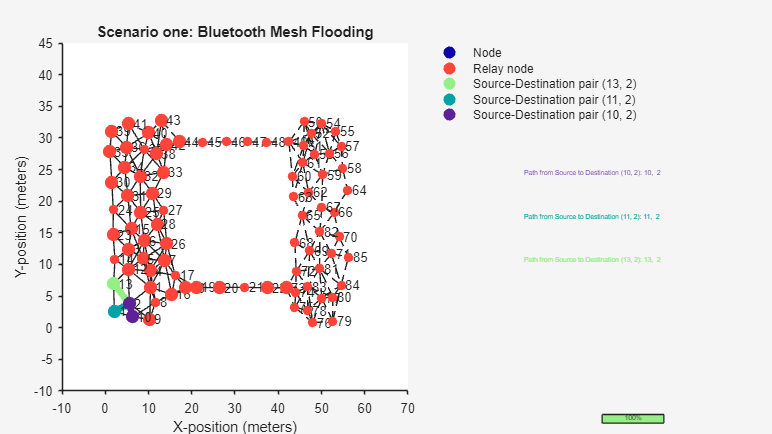

pdrSrenarioOne = 1

pathScenarioOne = 5×4 table
    Source    Destination           Path           NumberOfHops
    ______    ___________    __________________    ____________

      13           2         {[          13 2]}         1      
      11           2         {[          11 2]}         1      
      10           2         {[          10 2]}         1      
       9           2         {[        9 10 2]}         2      
       8           2         {[8 9 10 11 13 2]}         5      


[pdrSrenarioOne,pathScenarioOne] = meshResults(eventsScenarioOne,statisticsScenarioOne)

%[pdrScenarioTwo,pathScenarioTwo] = meshResults(eventsScenartioTwto,statisticsScenarioTwo)

The obtained results show that there exists a path between the source and destination nodes even if nodes fail randomly in the network.

## Further Exploration

To obtain numerical results averaged over multiple simulations, the example implements the Monte Carlo method [ 4 ]. To implement Monte Carlo simulations, use the [helperBLEMeshMonteCarloSimulations](matlab:edit('helperBLEMeshMonteCarloSimulations')) helper function. During each simulation run, perform these steps.

- Use a new seed to generate a random number

- Randomly disable the relay nodes until a path exist between the source and destination nodes

- Store the PDR value

The Monte Carlo simulations outputs critical relay nodes required to ensure message delivery from the source to destination. The example performs Monte Carlo simulations by using these configuration parameters.

% Relay nodes
%relayNodes = [3 6 7 8 9 12 13 14 15 17];

% Source and destination pair
%sourceDestinationPairs = [1 10];

% TTL value for messages originated from the source
%ttl = 10;

To view the simulation results, see `bleMeshMonteCarloResults` MAT file.

%load("bleMeshMonteCarloResults.mat");
%disp("Further exploration: Nodes [" + num2str(criticalRelaysInfo{1:5,1}') + ...
%    "] are the top 5 critical relays for having communication between Node1 and Node10.");

## Appendix

The example uses these helpers:

- [helperBLEMeshEventCallback](matlab:edit('helperBLEMeshEventCallback')): Callback function to visualize message transmissions

- [helperBLEMeshVisualizeNetwork](matlab:edit('helperBLEMeshVisualizeNetwork')): Bluetooth mesh network visualization

- [helperBLEMeshSimulateScenarioTwo](matlab:edit('helperBLEMeshSimulateScenarioTwo')): Configure and run mesh network for scenario two

- [helperBLEMeshMonteCarloSimulations](matlab:edit('helperBLEMeshMonteCarloSimulations')): Bluetooth mesh network Monte Carlo simulations

## Selected Bibliography

- Bluetooth Technology Website. “Bluetooth Technology Website | The Official Website of Bluetooth Technology.” Accessed May 24, 2022. [https://www.bluetooth.com](https://www.bluetooth.com).

- Bluetooth Special Interest Group (SIG). "Bluetooth Core Specification." Version 5.3. [https://www.bluetooth.com/.](https://www.bluetooth.com)

- Bluetooth Special Interest Group (SIG). "Bluetooth Mesh Profile." Version 1.0.1 [https://www.bluetooth.com/.](https://www.bluetooth.com)

- Metropolis, Nicholas, and S. Ulam. "The Monte Carlo Method." *Journal of the American Statistical Association* 44, no. 247 (September 1949): 335–41. [https://doi.org/10.1080/01621459.1949.10483310](https://doi.org/10.1080/01621459.1949.10483310).

*Copyright 2019-2023 The MathWorks, Inc.*